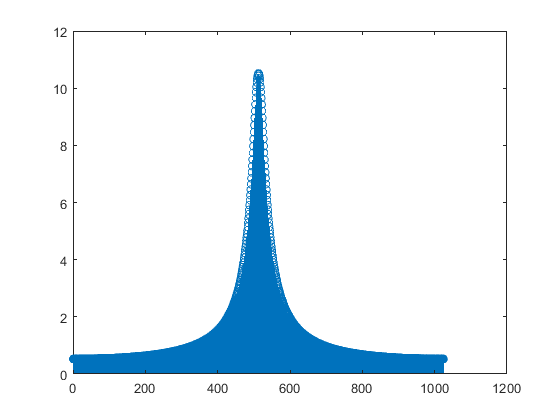

Fs = 1000;
Ts = 1/Fs;
N = 1024;
t = 0:Ts:(N-1)*Ts;
xn = exp(-100*t);
XW = fftshift(fft(xn));
stem(abs(XW));

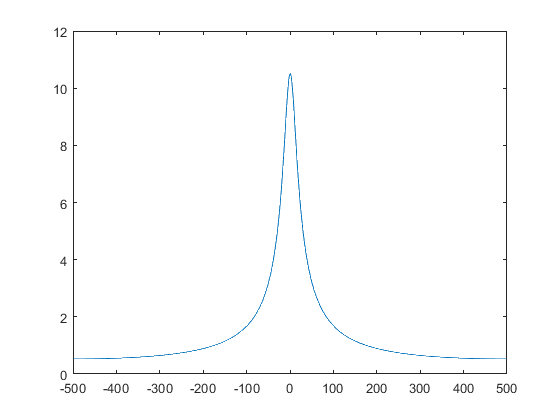

F = -Fs/2:Fs/(N-1):Fs/2;
plot(F,abs(XW))

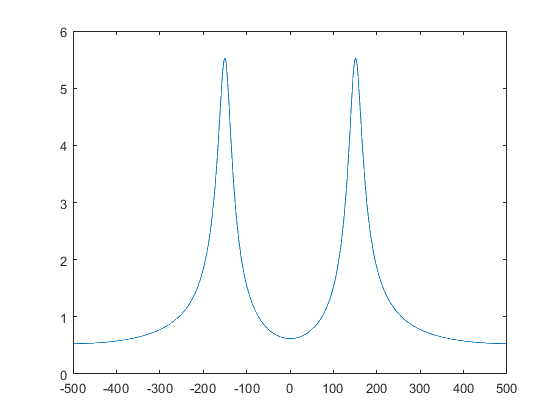

Fs = 1000;
Ts = 1/Fs;
N = 1024;
t = 0:Ts:(N-1)*Ts;
xn = exp(-100*t) .* cos(2*pi*150*t);
XW = fftshift(fft(xn));
F = -Fs/2:Fs/(N-1):Fs/2;
plot(F, abs(XW))

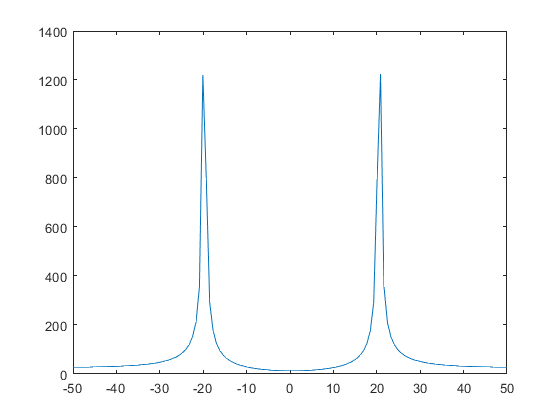

Fs = 100;
Ts = 1/Fs;
N = 128;
t = 0:Ts:(N-1)*Ts;
xn = 5*cos(2*pi*20*t) + 20*cos(2*pi*80*t);
XW = fftshift(fft(xn));
F = -Fs/2:Fs/(N-1):Fs/2;
plot(F, abs(XW))

Fs = 100;
F = 6;
w0 = 2*pi*F/Fs;
b = [1 -2*cos(w0) +1]

b =     1.0000   -1.8596    1.0000


a = [1 -2*0.9*cos(w0) 0.9^2]

a =     1.0000   -1.6736    0.8100


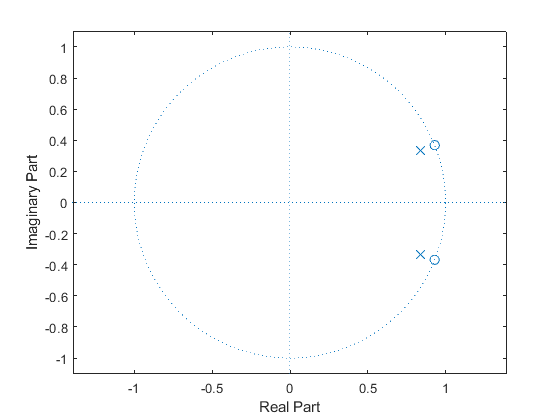

zplane(b,a)

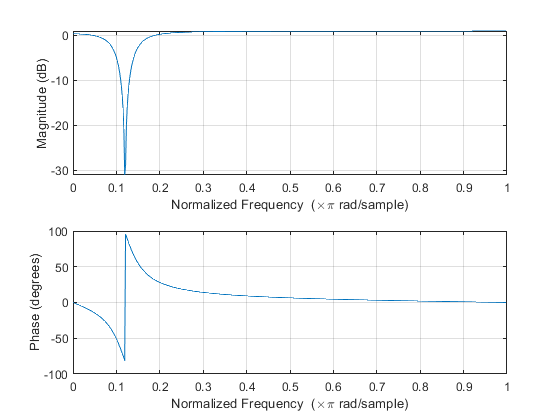

freqz(b,a)